# **Motivation**

Fluids are all around us and understanding their dynamics is a fundamental aspect of engineering. Their importance cannot be understated. Engineers use the principles of fluid dynamics in designing aerodynamic and hydrodynamic systems. A basic understanding of fluids dates to pre-history, with civilizations harnessing the power of fluids through aqueducts. Nowadays, fluid dynamics is studied to send rockets into space, improve wind energy harvesting, advance medical procedures and much more. Up until the 20th century, there were two methods of analysis, theoretical and experimental. In theoretical analysis, exact or approximate solutions are found to the governing equations of flow. In experimental, relationships are found to predict fluid behavior. With the development of computers, a third branch of study began, computational fluid dynamics. In computational research, scientists solve the governing equations of flow using numerical methods to approximate a solution to the flow field. This allows powerful computers to solve problems which do not have theoretical solutions or problems which cannot be tested experimented. It has given insight into problems previously never understood. And, in this teaching module, we are going to learn how to develop an incompressible CFD solver.

### Learning Objectives

- Derive and understand the constitutive equations of fluid dynamics.

- Understand how t the numerical domain for solving the problem of interest.

- Formulate boundary conditions for lid driven cavity flow.

- Understand how to use the finite volume method to solve for the intermediate velocity flow field.

- Use the two-step projection method decouples the new velocity field with the pressure field.

- Solve the pressure Poission equation using successive over relaxation.

- Learn to update the velocity field.

### **Governing equations**

The basics of CFD begin with the governing equations of flow, the continuity equation, momentum equation and energy equation. These mathematical equations are based on three fundamental conservation laws:

- The conservation of mass.

- Newton's second law of motion, F=ma.

- The conservation of energy.

To begin, we will derive the first two fundamental equations. The conservation of energy is outside the scope of this module. For additional insight, please see *Computational-Fluid-Dynamics-the-Basics-With-Applications**.*

#### Conservation of mass

To understand the equations, let's do a thought experiment. Imagine there is a flow field, and inside that flow field is a fluid parcel of arbitrary shape and of finite size. The fluid parcel is fixed in space and fluid is moving across its surface. If mass must be conserved, what must be true about the net mass flow through the parcel? Well, any flow into the parcel should be equal to the flow leaving the parcel, if mass is conserved. And, the flow inside the parcel should change over time with respect to flow passing through. As such:

Net mass flow out of the fluid parcel (A) = -Time rate of change of mass inside the fluid parcel (B)

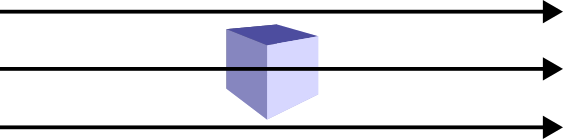

If this is true, let's find an equation for A and an equation for B. The mass flow through any surface of the cube should be (density of the fluid $\rho$) x (velocity of the fluid normal to the face $U_n$) x (area of the face $ds$):


$$\rho U_n dS$$


To find the mass flux through all the faces, integrate over all surfaces of the cube:


$$A = \int_S \rho U dS$$


Now, consider B, the total mass inside the cube which is the density of fluid, integrated over the control volume:


$$B = -\frac{\partial}{\partial t}\int_V \rho dV$$


Setting $A = B$, and completing the integral:


$$\int_S \rho U dS = -\frac{\partial }{\partial t}\int_V \rho dV$$



$$\partial (\rho u)dydz + \partial (\rho v)dxdz + \partial (\rho w)dxdy = -\frac{\partial \rho}{\partial t} dxdydz$$



$$\frac{\partial (\rho u)}{dx} + \frac{\partial (\rho v)}{dy} + \frac{\partial (\rho w)}{dz}= -\frac{\partial \rho}{\partial t}$$


This can be simplified and written in compact form, giving the equation for conservation of mass:


$$\frac{\partial \rho}{dt} + \nabla \cdot (\rho \vec{U}) = 0$$


where $\vec{U}$ is a vector of $[\matrix{u & v & w} ]$ velocity components. A special case exists for incompressible flow, where density is constant within a fluid parcel. Essentially, the flow field is divergence free, which yields the continuity equation:


$$\nabla \cdot \vec{U} = 0$$


#### Conservation of momentum

To conserve momentum, we begin with Newton's second law of motion $F = ma$, and apply it to the fluid parcel. However, this begs the question, what forces exist on a fluid parcel? Well, these include two classes of forces: body forces and surface forces. In general, body forces act throughout the entire volume of the body and occur at a distance. Some body forces are gravity, electric fields, and magnetic fields. On the other hand, surface forces act directly on the fluid volume, either normal to the surface or tangential (shear force). They occur due to either pressure gradients imposed by the surrounding fluid, or shear and normal stress distributions by the outside fluid pushing or sliding across the surface creating friction.

Without going into painstaking detail, let's begin with the fluid parcel and derive the force balance for all forces in the x-direction. Notice, that all forces on the cube are in the x-direction, consistent with the notation used in the xyz coordinate system. The vector directions are consistent with positive increases along the axis in that direction. 

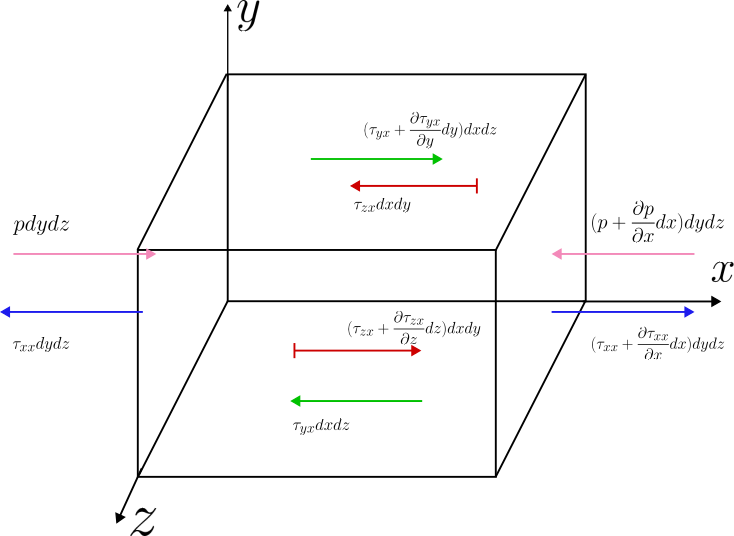

Writing the net surface flux in the x direction yields:


$$F_x = (p - (p + \frac{\partial p}{\partial x}dx)dydz) + ((\tau_{xx} + \frac{\tau_{xx}}{\partial x})dx - \tau_{xx})dydz + ((\tau_{yx} + \frac{\tau_{yx}}{\partial y})dy - \tau_{yx})dxdz + ((\tau_{zx} + \frac{\tau_{zx}}{\partial z})dz - \tau_{zx})dxdy $$


Simplifying the terms and adding in the additional body force due to gravity, the sum of the forces in x is given by:


$$F_x = (-\frac{\partial p}{\partial x} + \frac{\partial \tau_{xx}}{\partial x} + \frac{\partial \tau_{yx}}{\partial y} + \frac{\partial \tau_{zx}}{\partial z})dxdydz + \rho f_x dx dy dz$$


According to Newton's second law of motion, the force balance equals (mass) x (acceleration). The mass in the control volume is the (density of the fluid) x (control volume), and the acceleration is the [substantial derivative](https://en.wikipedia.org/wiki/Material_derivative) of the velocity. Setting $F_x = ma_x$ yields the x momentum equation:


$$\rho \frac{Du}{Dt} = -\frac{\partial p}{\partial x} + \frac{\partial \tau_{xx}}{\partial x} + \frac{\partial \tau_{yx}}{\partial y} + \frac{\partial \tau_{zx}}{\partial z} + \rho f_x$$


Performing the same analysis for the y and z directions yield the y momentum equation and z momentum equation respectively:


$$\rho \frac{Dv}{Dt} = -\frac{\partial p}{\partial y} + \frac{\partial \tau_{xy}}{\partial x} + \frac{\partial \tau_{yy}}{\partial y} + \frac{\partial \tau_{zy}}{\partial z} + \rho f_y$$



$$\rho \frac{Dw}{Dt} = -\frac{\partial p}{\partial z} + \frac{\partial \tau_{xz}}{\partial x} + \frac{\partial \tau_{yz}}{\partial y} + \frac{\partial \tau_{zz}}{\partial z} + \rho f_z$$


In this convention, $\vec{U}$ is the velocity vector with $u, v, w$ velocity components in the $x, y, z$ directions respectively. The equations can also be obtained in conservation form. Using the x momentum equation as an example and rewriting the substantial derivative:


$$A = \rho \frac{Du}{Dt} = \rho \frac{\partial u}{\partial t} + \rho \vec{U} \cdot \nabla u$$


Knowing that the following derivative expands to:


$$\frac{\partial (\rho u)}{\partial t} = \rho \frac{\partial u}{\partial t} + u \frac{\partial \rho}{\partial t}$$



$$\rho \frac{\partial u}{\partial t} = \frac{\partial (\rho u)}{\partial t} - u \frac{\partial \rho}{\partial t}$$


We can substitute the previous into the substantial derivative:


$$A = \rho \frac{Du}{Dt} = \frac{\partial (\rho u)}{\partial t} - u \frac{\partial \rho}{\partial t} + \rho \vec{U} \cdot \nabla u$$


Also recognizing the following relationship:


$$\nabla \cdot (\rho u \vec{U}) = u \nabla \cdot (\rho \vec{U}) + (\rho \vec{U}) \cdot \nabla u$$



$$ (\rho \vec{U}) \cdot \nabla u =  \nabla \cdot (\rho u \vec{U}) - u \nabla \cdot (\rho \vec{U})$$


Substituting the previous into substantial derivative:


$$A = \rho \frac{Du}{Dt} = \frac{\partial (\rho u)}{\partial t} - u \frac{\partial \rho}{\partial t} +  \nabla \cdot (\rho u \vec{U}) - u \nabla \cdot (\rho \vec{U})$$


Rearranging:


$$\rho \frac{Du}{Dt} = \frac{\partial (\rho u)}{\partial t} +  \nabla \cdot (\rho u \vec{U}) - u (\frac{\partial \rho}{\partial t}  -  \nabla \cdot (\rho \vec{U}))$$


We see the second term is the equation for conservation of mass which equals zero. Substituting the substantial derivative back into the x momentum equation the x momentum equation in conservation form is obtained:


$$ \frac{\partial (\rho u)}{\partial t} +  \nabla \cdot (\rho u \vec{U}) = -\frac{\partial p}{\partial x} + \frac{\partial \tau_{xx}}{\partial x} + \frac{\partial \tau_{yx}}{\partial y} + \frac{\partial \tau_{zx}}{\partial z} + \rho f_x$$


And even more compactly, all the momentum equations can be written in vector notation, giving the Navier-Stokes equations:


$$\frac{\partial (\rho \vec{U})}{\partial t} + \nabla \cdot(\rho \vec{U} \vec{U}) = -\nabla P + \nabla \cdot \tau + \vec{F_B}$$



$$\tau = \mu(\nabla \vec{U} + \nabla \vec{U^T})$$



$$\nabla \cdot \tau = \mu \nabla^2  \vec{U}$$


Now that the governing equations have been established, how should they be solved? If you analyze the equations closely you will notice we have 4 equations, x momentum, y momentum, z momentum and the continuity equation, but no relationship for determining pressure. To solve this, we decouple the velocity calculation with the pressure by using the two step projection method ([Chorin](https://www.ams.org/journals/mcom/1968-22-104/S0025-5718-1968-0242392-2/S0025-5718-1968-0242392-2.pdf)). In other words, the equations are split into two parts, the first without pressure:


$$\frac{\rho^{n+1} \vec{U^*} - \rho^n \vec{U^n}}{\Delta t} = -\nabla \cdot(\rho \vec{U} \vec{U})^n + \nabla \cdot \tau^n$$
      
$$(\mathcal{A})$$



$$\frac{\rho^{n+1} \vec{U^{n+1}} - \rho^{n+1} \vec{U^*}}{\Delta t} = -\nabla p^{n+1}$$
       
$$(\mathcal{B})$$


In equation $(\mathcal{A})$, everything is known, including $\rho^{n+1}$. In this flow solver, the density flux is constant since it is incompressible and we are only dealing with a single phase. So, the intermediate velocity $\vec{U^*}$ can be easily solved. However, in equation $(\mathcal{B} )$ there are two unknowns $\vec{U^{n+1}}$ and $p^{n+1}$. The continuity equation states that the velocity must be divergence free. Taking the divergence of equation $(\mathcal{B} )$ gives:


$$\nabla \cdot (\frac{\rho^{n+1} \vec{U^{n+1}} - \rho^{n+1} \vec{U^*}}{\Delta t}) = \nabla \cdot-\nabla p^{n+1}$$


The divergence free condition appears as $\nabla \cdot \vec{U^{n+1}} = 0$, and after canceling it out:


$$\frac{\nabla^2 p^{n+1}}{\rho^{n+1}} = -\frac{1}{\Delta t} \nabla \cdot \vec{U^*}$$
      
$$(\mathcal{C})$$


Equation $(\mathcal{C})$ is the pressure Poisson equation. Using an iterative solver, it will yield a pressure field which can be used to solve for $\vec{U^{n+1}}$ in equation $(\mathcal{B})$.

### **How to solve the Navier-Stokes equations**

For simplicity, we are going to solve the 2D Navier-Stokes equations for incompressible flow. The solution procedure is broken down into the following main steps.

- Setup the problem.

- Initialize variables and set up the grid.

- Initiate the boundary conditions.

- Calculate the intermediate velocity.

- Solve the pressure Poisson equation.

- Update the velocity at the next time step.

#### Problem setup

The model problem is lid driven cavity flow. This is a classic benchmark test case for CFD codes, mainly because of the simplicity of the geometry and the specific boundary conditions used. In this problem, a no slip, no penetration boundary condition is applied to the walls. Essentially, this is a closed box of fluid, with no new fluid entering. The flow develops because of the moving lid, which has a velocity of 1 m/s. By solving the NSE, a flow field of the fluid's velocity is obtained within the cavity.

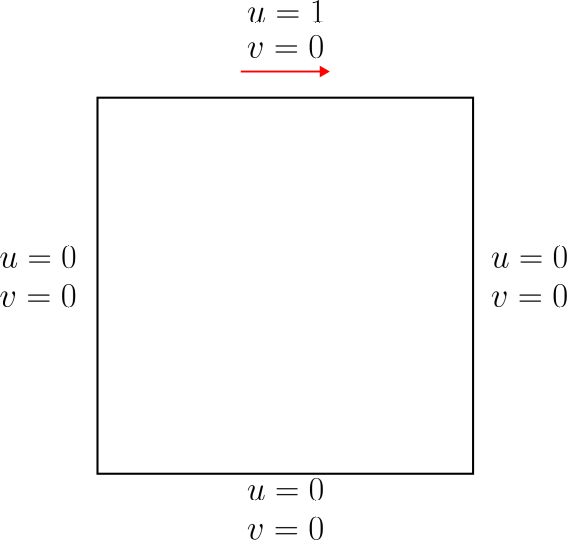

#### Initialize variables and set up grid

To solve the NSE we are going to use the finite volume method (FVM). If you don't have experience using FVM, it is very similar to finite different methods. Instead, of solving the partial differential equations in differential form, they are solved in integral form. The resulting stencils end up being almost identical. FVM is used because it is the perfect choice for problems with staggered grids (grids where scalars are at cell centers and vectors at cell faces). Often, FDM are used with collocated grids (all values are at the same grid points). In solving the NSE, collocated grids lead to odd-even velocity decoupling. 

As noted, we are using a staggered grid as seen below. In this setup, pressure is denoted at the cell center of cell (j, i). Velocities are denoted at cell faces to the minus side. For instance, $u_{j, i}$ is at the left face in cell (j, i) and $v_{j, i}$ is at the bottom face in cell (j, i). Note, that this index notation is being used so there is agreement with index positions in MATLAB matrices. 

**Important: **

 When indexing on the staggered grid, only consider the staggered grid index relationship. This is also true for the standard grid (will be clearer when we begin indexing). Use the two figures below as your reference. Indexing is arguably the most confusing part of solving these equations!

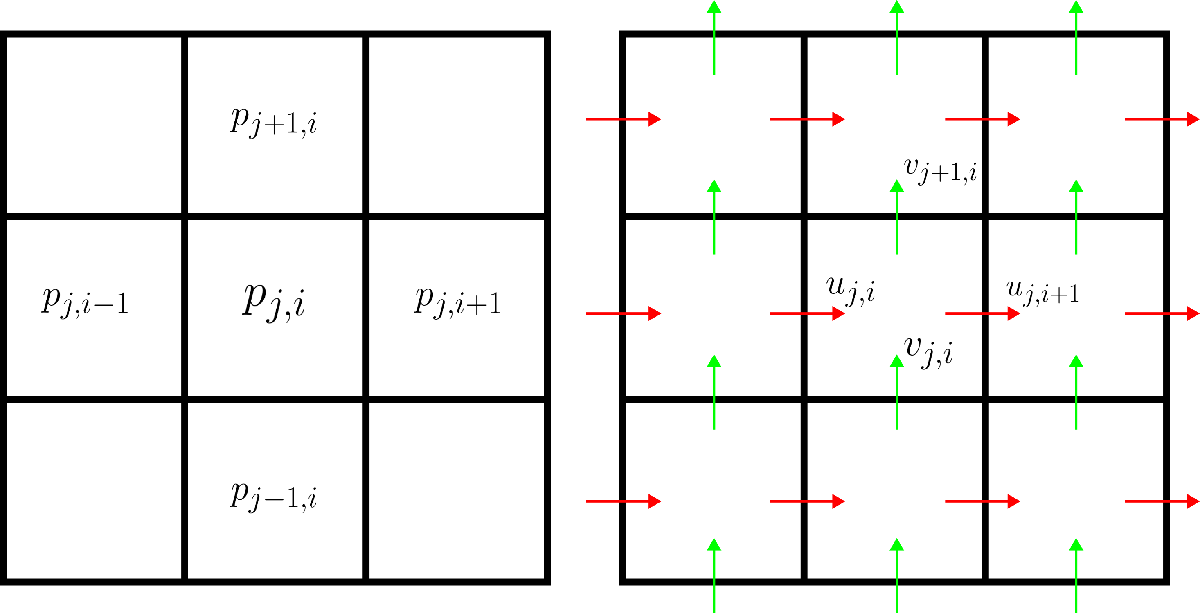

The standard grid indexes are defined as follows:

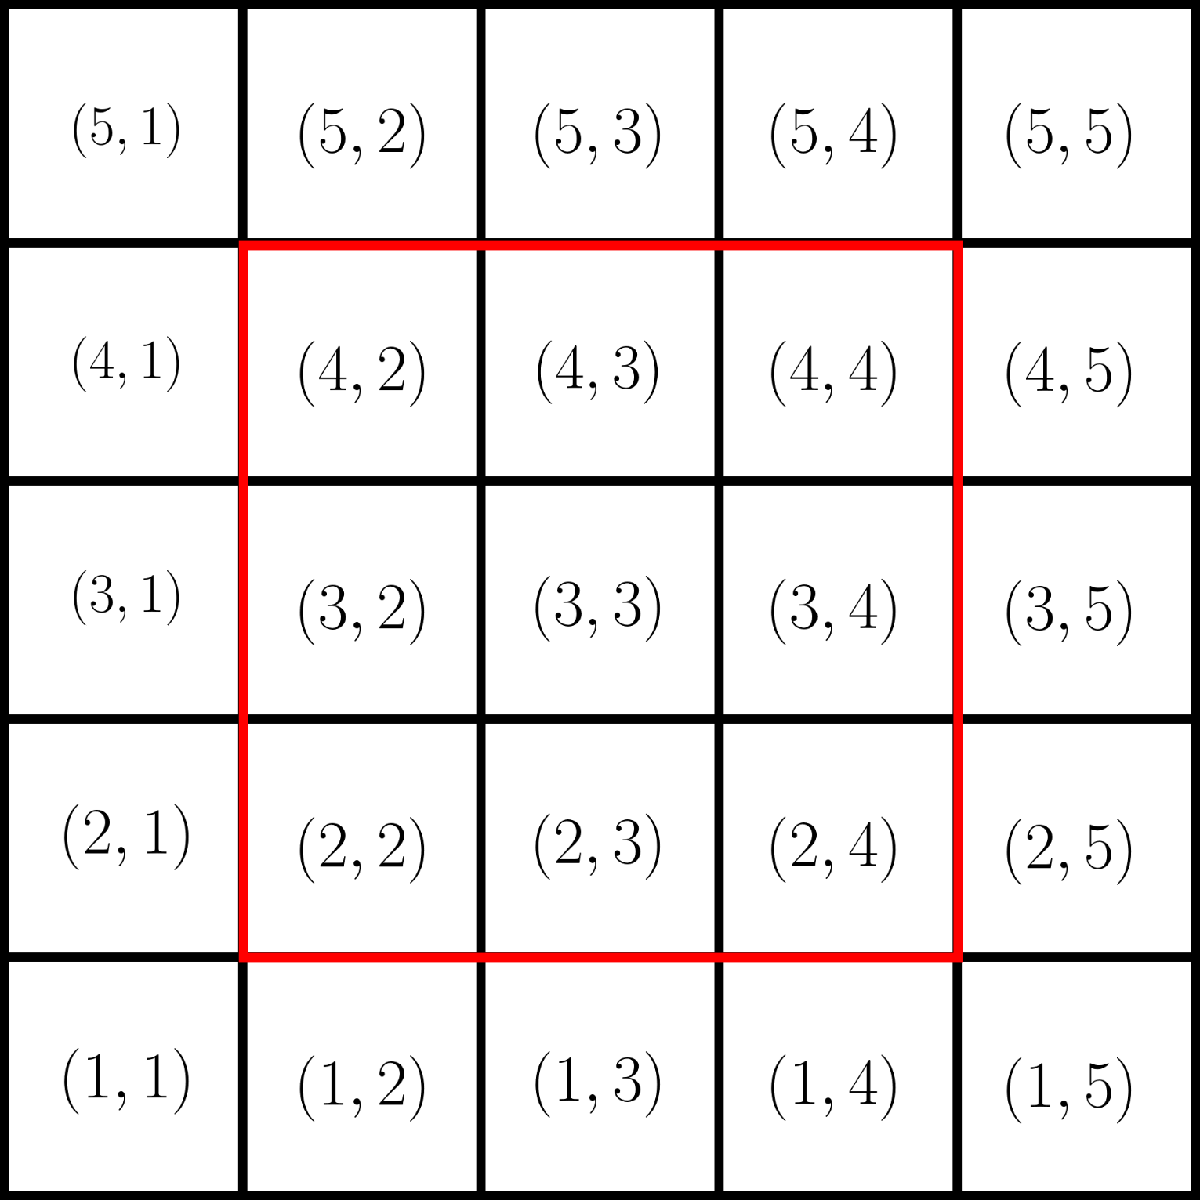

Here the red box represents the real domain boundary. The outside cells are ghost cells which are useful for setting reference pressure values and specifying cell face velocities. The internal domain will have a number of cells equal to $nx
$ by $ny$. Thus, the variables will be indexed to $nx+2$ and $ny+2$ to account for the ghost cells. To set up the problem, let's first define the grid. The ghost cell indices are thus located at

- 
$$j=(1,ny+2) \text{ for } i \in [1, nx+2]$$


- 
$$i=(1,nx+2) \text{ for } j \in [1, ny+2]$$


 **Run each section of code as we reach it.**

% Domain setup
xe = 1.0; % Domain length in x
ye = 1.0; % Domain length in y

nx = 8; % Number of cells in x
ny = 8; % Number of cells in y

dx = xe/nx; % Cell size x
dy = ye/ny; % Cell size y


Now, initialize the variables, using the grid indexing described. All the variables are initialized to zero.

% Initialize variables
u = zeros(ny+2,nx+2); % Face centered u velocity (to the left face)
v = zeros(ny+2,nx+2); % Face centered v velocity (to the bottom face)
p = zeros(ny+2,nx+2); % Cell centered pressure
div = zeros(ny+2,nx+2); % Cell centered divergence

u_old = zeros(ny+2,nx+2);
v_old = zeros(ny+2,nx+2);

rho = 1.0; % Fluid density (kg/m^3)
mu = 0.01; % Fluid viscosity (Pa.s)

initialVelocity = 1.0; % Top wall u velocity

dt = min(0.25*dx*dx/(mu/rho),4.0*mu/rho/initialVelocity/initialVelocity); % Time step (linear advection diffusion stability condition)

As you can see, cell centered values and face centered values are all indexed with 2 extra cells. The first u velocity $u_{1,1}$ is the bottom most left face of the grid, it is also located at the ghost boundary. $u_{2, 2}$, is the left face velocity at the real (red) domain boundary. 

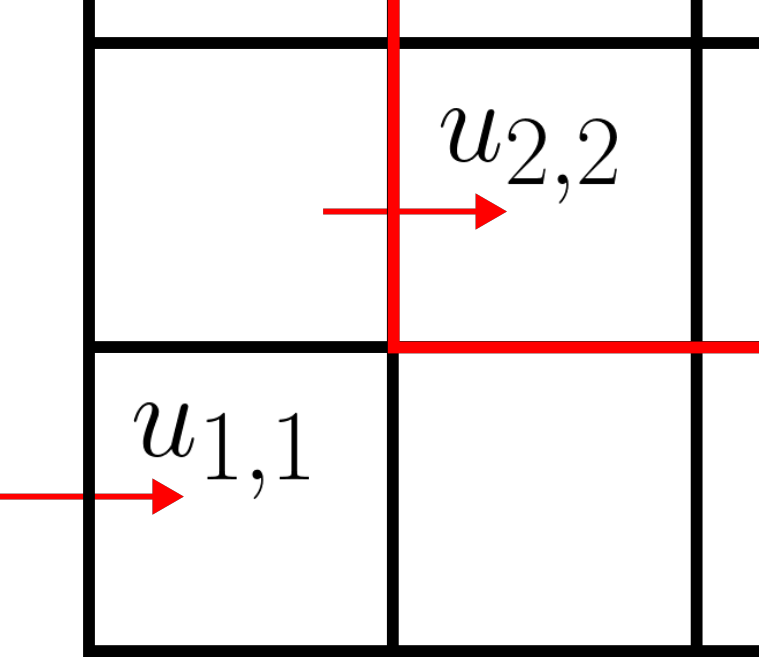

#### Boundary conditions

As denoted in the problem setup, lid driven cavity flow only has one specified velocity at the top face. However, a velocity can be specified at any face along the boundary. The code below accounts for all possible faces.

% Parallel to wall
ut = initialVelocity; % Top wall 
ub = 0.0; % Bottom wall
vl = 0.0; % Left wall
vr = 0.0; % Right wall

% Perpendicular to wall
ul = 0.0; % Left wall
ur = 0.0; % Right wall
vt = 0.0; % Top wall
vb = 0.0; % Bottom wall

Looking at the grid boundary, there is no u velocity component which can be set at exactly the wall boundary. That wall boundary only has v velocity components. This is where ghost cells come into play and are used to specify ghost cell velocities. To set the velocity at the wall, the ghost cell velocity is set such that the average between the two is the wall velocity.

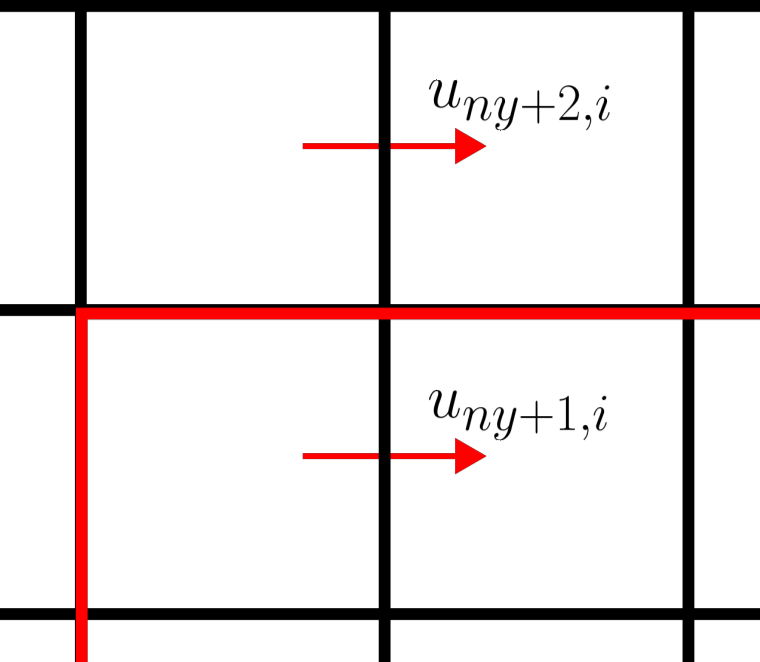


$$u_t = \frac{u_{ny+2,i} + u_{ny+1, i}}{2}$$


#### 
$$u_{ny+2, i} = 2u_t - u_{ny+1, i}$$


Following this same methodology, the other boundary conditions for each wall are set. Velocities perpendicular to cell boundaries can be set directly.

 Run the following code and try to follow how the u velocities are indexed. Also note, that the matrix will appear flipped, and velocities will appear to be at cell centers, but remember they are shifted over to the minus side!

u_old(:,2) = ul; % Left wall
u_old(:,nx+2) = ur; % Right wall
u_old(ny+2,:) = 2*ut - u_old(ny+1,:); % Top wall
u_old(1,:) = 2*ub - u_old(2,:); % Bottom wall

v_old(ny+2,:) = vt; % Top wall
v_old(2,:) = vb; % Bottom wall
v_old(:,1) = 2.0*vl - v_old(:,2); % Left wall
v_old(:,nx+2) = 2.0*vr - v_old(:,nx+1); % Right wall;

v = v_old;
u = u_old

u =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     2     2     2     2     2     2     2     2     2     2


#### Intermediate velocity

To solve the Navier Stokes equations, start by taking the volume integral of both sides of equation $(\mathcal{A})$. The superscript from $\rho$ can be dropped, since this solver only deals with a single fluid, and density has no time rate of change.


$$\int_V\frac{\rho \vec{U^*} - \rho \vec{U^n}}{\Delta t} dV= -\int_V \nabla \cdot(\rho \vec{U} \vec{U})^n dV + \mu \int_V\nabla \cdot \nabla \vec{U^n} dV$$


Using the divergence theorem, this equation is brought into a more usable form. The divergence theorem states that the flux through a surface is equal to the volume integral of the divergence within that surface. This holds true for closed surfaces in the absence of the creation or destruction of mass. Converting the volume integrals to surface integrals, and evaluating the left-hand side, the equation becomes:


$$\frac{\rho \vec{U^*} - \rho \vec{U^n}}{\Delta t} dxdy= -\int_S (\rho \vec{U} \vec{U})^n \cdot \vec{n} dS + \mu \int_S \nabla \vec{U^n} \cdot \vec{n} dS$$


This equation is still in its exact form. At this point, no approximations have been made. The flux integrals can be split up over an arbitrary surface. In our case, we have a cartesian grid, and each cell consists of four linear surfaces. The four faces are denoted as east, west, north, and south.


$$\frac{\rho \vec{U^*} - \rho \vec{U^n}}{\Delta t} dxdy= -\sum_{f1,f2, ...}\int_{S_i} (\rho \vec{U} \vec{U})^n \cdot \vec{n} dS + \mu \sum_{f1,f2, ...}\int_{S_i} \nabla \vec{U^n} \cdot \vec{n} dS$$


Now, let's break up this equation into its x and y components:


$$\frac{\rho u^* - \rho u^n}{\Delta t} dxdy= -\sum_{f1,f2, ...}\int_{S_i} (\rho u \vec{U})^n \cdot \vec{n} dS_i + \mu \sum_{f1,f2, ...}\int_{S_i} \nabla u^n \cdot \vec{n} dS_i$$
      
$$(\mathcal{x})$$



$$\frac{\rho v^* - \rho v^n}{\Delta t} dxdy= -\sum_{f1,f2, ...}\int_{S_i} (\rho v \vec{U})^n \cdot \vec{n} dS_i + \mu \sum_{f1,f2, ...}\int_{S_i} \nabla 
v^n \cdot \vec{n} dS_i$$
      
$$(\mathcal{y})$$


Starting with equation $(\mathcal{x})$, let's evaluate the convective flux (at cell faces). Use the below figure for reference.

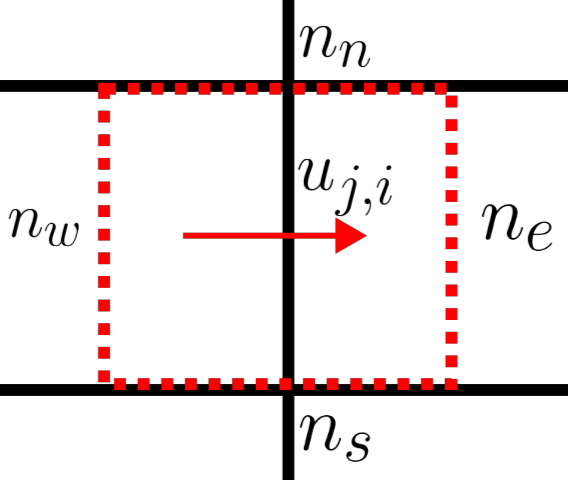


$$\sum_{f1,f2, ...}\int_{S_i} (\rho u \vec{U})^n \cdot \vec{n} dS_i = \int_e (\rho u u)^n_e dS_e - \int_w (\rho u u)^n_w dS_w + \int_n(\rho v u)^n_n dS_n - \int_s (\rho v u)^n_s dS_s$$


Evaluating the integrals using numerical integration, more specifically the midpoint rule, they are approximated as:


$$\sum_{f1,f2, ...}\int_{S_i} (\rho u \vec{U})^n \cdot \vec{n} dS_i = (\rho u u)^n_e dy - (\rho u u)^n_w dy + (\rho v u)^n_n dx - (\rho v u)^n_s dx$$
      
$$(\mathcal{c)$$


Use the below figure for reference in performing the same type of analysis with the diffusive flux in equation $(\mathcal{x})$.

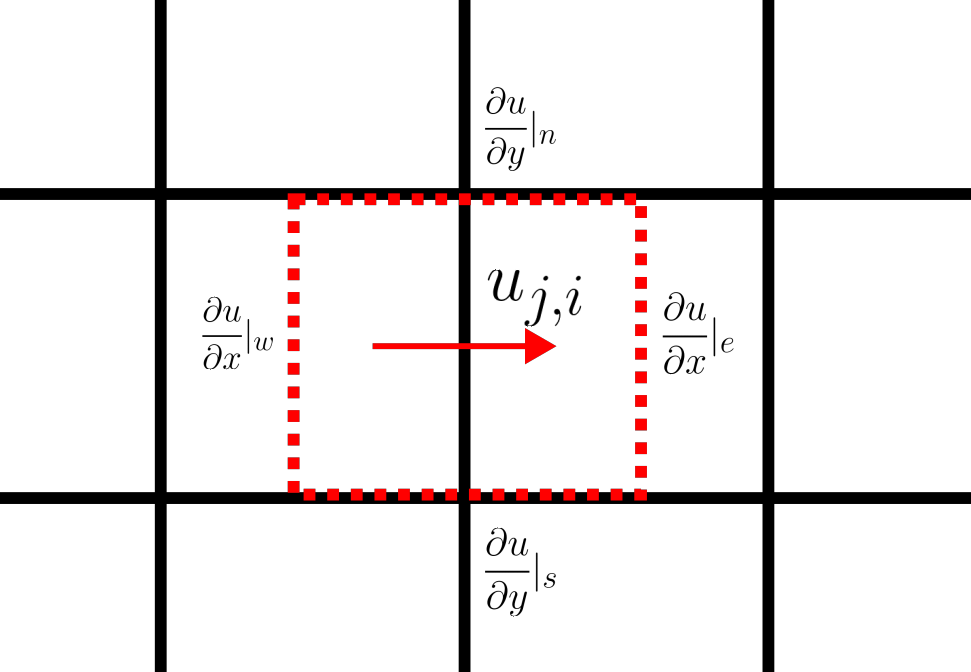


$$\sum_{f1,f2, ...}\int_{S_i} \nabla u^n \cdot \vec{n} dS_i = \int_e \frac{\partial u^n}{\partial x}|_e dS_e - \int_w \frac{\partial u^n}{dx}|_w dS_w + \int_n \frac{\partial u^n}{\partial y}|_n dS_n - \int_s \frac{\partial u^n}{\partial y}|_s dS_s$$



$$\sum_{f1,f2, ...}\int_{S_i} \nabla u^n \cdot \vec{n} dS_i = \frac{\partial u^n}{\partial x}|_e dy - \frac{\partial u^n}{dx}|_w dy + \frac{\partial u^n}{\partial y}|_n dx - \frac{\partial u^n}{\partial y}|_s dx$$


Now, evaluate the partial u derivatives, using central differencing.


$$\sum_{f1,f2, ...}\int_{S_i} \nabla u^n \cdot \vec{n} dS_i = \frac{dy}{dx}(u_{j, i+1} - u_{j,i}) - \frac{dy}{dx}(u_{j, i} - u_{j,i-1}) + \frac{dx}{dy}(u_{j+1, i} - u_{j,i}) - \frac{dx}{dy}(u_{j, i} - u_{j-1,i})$$
      
$$(\mathcal {d} )$$


Inserting equation $(\mathcal{c})$ and equation $(\mathcal{d})$ back into equation $(\mathcal{x})$, and simplifying terms, yields the intermediate velocity equation (x):


$$\frac{\rho u^* - \rho u^n}{\Delta t} =  -(\frac{(\rho u u)^n_e}{dx} - \frac{(\rho u u)^n_w}{dx}) -(\frac{(\rho v u)^n_n}{dy} - \frac{(\rho v u)^n_s}{dy}) + \mu \frac{u_{j, i+1} - 2u_{j,i} + u_{j,i-1}}{dx^2} + \mu \frac{u_{j+1, i} - 2u_{j,i} + u_{j-1,i}}{dy^2}$$


Performing the same analysis starting with equation $(\mathcal y)$ yields the intermediate velocity equation (y):


$$\frac{\rho v^* - \rho v^n}{\Delta t} =  -(\frac{(\rho v u)^n_e}{dx} - \frac{(\rho v u)^n_w}{dx}) -(\frac{(\rho v v)^n_n}{dy} - \frac{(\rho v v)^n_s}{dy}) + \mu \frac{v_{j, i+1} - 2v_{j,i} + v_{j,i-1}}{dx^2} + \mu \frac{v_{j+1, i} - 2v_{j,i} + v_{j-1,i}}{dy^2}$$


In the above two equations everything is known, and we are solving for the intermediate velocities $u^*$ and $v^*$. However, based on the grid, velocities at the east and west faces are not explicitly known. They must be interpolated using the nearest known velocity components.

 Notice the indexing and notation in the code below is exactly the same as the mathematical formulation.

% Looping through all cell faces inside our domain. u velocities at i=1 are 
% at a ghost face, i=2 are at the domain boundary, i=nx+2 is also a domain boundary
% so they are left out of the loop.
for i=3:nx+1
    for j=2:ny+1
        % Interpolating velocities
        u_e = 0.5*(u_old(j,i) + u_old(j,i+1));
        u_w = 0.5*(u_old(j,i-1) + u_old(j,i));
        u_n = 0.5*(u_old(j,i) + u_old(j+1,i));
        u_s = 0.5*(u_old(j,i) + u_old(j-1,i));

        v_n = 0.5*(v_old(j+1,i-1) + v_old(j+1,i));
        v_s = 0.5*(v_old(j,i-1) + v_old(j,i));

        % Solving div(rho*u*u) and div(tau)
        convection = -(rho*u_e*u_e - rho*u_w*u_w)/dx - ... 
                      (rho*v_n*u_n - rho*v_s*u_s)/dy;

        diffusion = mu*(u_old(j,i-1) - 2.0*u_old(j,i) + u_old(j,i+1))/dx/dx + ... 
                    mu*(u_old(j+1,i) - 2.0*u_old(j,i) + u_old(j-1,i))/dy/dy;

        % Calculate intermediate u velocity
        u(j,i) = rho*u_old(j,i) + dt*(diffusion + convection);
        u(j,i) = u(j,i)/rho;
    end
end

for i=2:nx+1
    for j=3:ny+1
        % Interpolating velocities
        v_e = 0.5*(v_old(j,i) + v_old(j,i+1));
        v_w = 0.5*(v_old(j,i) + v_old(j,i-1));
        v_n = 0.5*(v_old(j,i) + v_old(j+1,i));
        v_s = 0.5*(v_old(j,i) + v_old(j-1,i));

        u_e = 0.5*(u_old(j-1,i+1) + u_old(j,i+1));
        u_w = 0.5*(u_old(j-1,i) + u_old(j,i));

        % Solving div(rho*u*u) and div(tau)
        convection = -(rho*v_e*u_e - rho*v_w*u_w)/dx - ... 
                      (rho*v_n*v_n - rho*v_s*v_s)/dy;

        diffusion = mu*(v_old(j,i-1) - 2*v_old(j,i) + v_old(j,i+1))/dx/dx + ... 
                    mu*(v_old(j+1,i) - 2*v_old(j,i) + v_old(j-1,i))/dy/dy;

        % Calculate intermediate v velocity
        v(j,i) = rho*v_old(j,i) + dt*(diffusion + convection);
        v(j,i) = v(j,i)/rho;
    end
end

#### Pressure solver

Remember the pressure Poisson equation:


$$\frac{\nabla^2 p^{n+1}}{\rho^{n+1}} = \frac{1}{\Delta t} \nabla \cdot \vec{U^*}$$
      
$$(\mathcal{C})
$$


Now, that $\vec{U^*}$ has been obtained, a stencil can be built to solve for the pressure field. 

 The indexing here refers to the standard grid. The pressure values are at cell centers and the divergence of $\vec{U^*}$ is also at the cell center. Dropping the superscripts for readability, using a 2nd order central differencing stencil, equation $(\mathcal{C})$ becomes:


$$\frac{1}{\rho}(\frac{p_{j,i+1} - 2p_{j,i} + p_{j,i-1}}{dx^2} +  \frac{p_{j+1,i} - 2p_{j,i} + p_{j-1,i}}{dy^2}) = \frac{1}{\Delta t} (\frac{u_{j,i+1} - u_{j,i}}{dx} + \frac{v_{j+1,i} - v_{j,i}}{dy})$$


Essentially, we have a linear system of equations of the form $A\vec{x} = b$, and the pressure coefficients in the A matrix are $\frac{1}{\rho dx^2}, \frac{1}{\rho dy^2}$, with a central coefficient of $\frac{-4}{\rho dx^2}$. However, this is not the case at the boundary. The boundary requires special treatment for the pressure coefficients. To explain this let's revisit the continuity equation:


$$\nabla \cdot \vec{U^{n+1}} = 0$$



$$\frac{1}{dx}(u_{j,i+1} - u_{j,i})^{n+1} + \frac{1}{dy}(v_{j+1,i} - v_{j,i})^{n+1} = 0$$


We also know, from equation $(\mathcal{B} )$:


$$\frac{\rho^{n+1} \vec{U^{n+1}} - \rho^{n+1} \vec{U^*}}{\Delta t} = -\nabla p^{n+1}$$



$$u_{j,i}^{n+1} = u_{j,i}^* - \frac{\Delta t}{\rho} \frac{\partial p}{\partial x}|_{j,i}$$



$$v_{j,i}^{n+1} = v_{j,i}^* - \frac{\Delta t}{\rho} \frac{\partial p}{\partial y}|_{j,i}$$


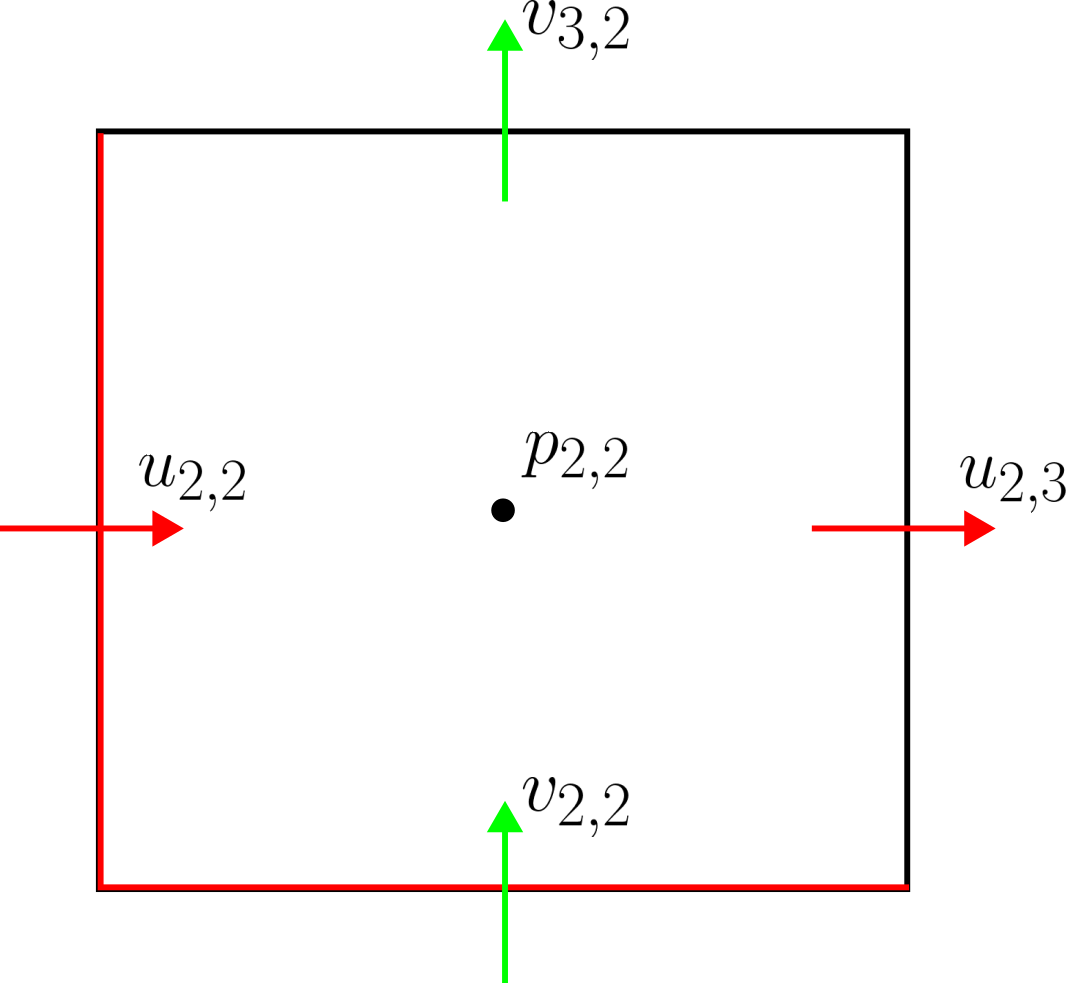

If we are at a boundary cell (2,2), velocities at the domain boundary are $u_{2,2} = v_{2,2} = 0$. This is known because they are physically set as our boundary condition. As a result, the continuity equation simplifies to:


$$\frac{1}{dx}(u_{j,i+1} )^{n+1} + \frac{1}{dy}(v_{j+1,i})^{n+1} = 0$$


Plugging velocities from equation $(\mathcal{B} )$ into above:


$$\frac{1}{dx} (u_{j,i+1}^* - \frac{\Delta  t}{\rho dx}(p_{j,i+1} - p_{j,i})) + \frac{1}{dy} (v_{j+1,i}^* - \frac{\Delta  t}{\rho dy}(p_{j+1,i} - p_{j,i}))$$


Rearranging:


$$\frac{1}{\rho} (\frac{p_{j,i+1} - p_{j, i}}{dx^2} + \frac{p_{j+1,i} - p_{j, i}}{dx^2}) = -\frac{1}{\Delta t}(\frac{u_{j,i+1}^*}{dx} + \frac{v_{j+1,i}^*}{dy})$$
      
$$(\mathcal{m})$$


Now, comparing equation $(\mathcal{m)$ to the stencil of equation $(\mathcal{C})$, there are some pressure terms missing. This is why those coefficients must be set to zero at the boundary. Following the same notation convention as previously, the following code uses an SOR iterative solver to solve the pressure Poisson equation to a residual tolerance of $10^{-11}$.

% Initializing variables and pressure coefficients
p = zeros(ny+2,nx+2);
rhs = zeros(ny+2,nx+2);
a_p = zeros(ny+2,nx+2);
a_e = ones(ny+2,nx+2)/rho/dx/dx;
a_w = ones(ny+2,nx+2)/rho/dx/dx;
a_n = ones(ny+2,nx+2)/rho/dy/dy;
a_s = ones(ny+2,nx+2)/rho/dy/dy;

% Pressure coefficients along domain boundary
a_e(:,nx+1) = 0.0;
a_w(:,2) = 0.0;
a_n(ny+1,:) = 0.0;
a_s(2,:) = 0.0;

% Central pressure coefficient
a_p = -(a_e + a_w + a_n + a_s);

% Pressure solver tolerance
TOL = 1e-11;
beta = 1.872;
maxError = 10;

while (abs(maxError) > TOL)
    maxError = 0;

    % Solve for pressure field
    for i=2:nx+1
        for j=2:ny+1
            rhs(j,i) = (u(j,i+1) - u(j,i))/dx + (v(j+1,i) - v(j,i))/dy;
            rhs(j,i) = rhs(j,i)/dt - (a_w(j,i)*p(j,i-1) + a_e(j,i)*p(j,i+1) + a_n(j,i)*p(j+1,i) + a_s(j,i)*p(j-1,i));
            p(j,i) = beta*rhs(j,i)/a_p(j,i) + (1-beta)*p(j,i);
        end
    end

    % Determine residuals
    for i=2:nx+1
        for j=2:ny+1
            rhs(j,i) = (u(j,i+1) - u(j,i))/dx + (v(j+1,i) - v(j,i))/dy;
            error = a_w(j,i)*p(j,i-1) + a_e(j,i)*p(j,i+1) + a_n(j,i)*p(j+1,i) + a_s(j,i)*p(j-1,i) + a_p(j,i)*p(j,i) - rhs(j,i)/dt;
            if abs(error) > maxError
                maxError = abs(error);
            end
        end
    end
end

#### Advance time step

Now that the pressure field has been established, the velocity at the next time step can be solved for using equation $(\mathcal {B} )$


$$\frac{\rho^{n+1} \vec{U^{n+1}} - \rho^{n+1} \vec{U^*}}{\Delta t} = -\nabla p^{n+1}$$
      
$$(\mathcal{B} )$$


 Notice the indexing for updating the velocity in each loop. Only interior cell face velocities are updated, since the boundary conditions for real domain face velocities are already set.

for i=3:nx+1
    for j=2:ny+1
        % Update u velocity
        u(j,i) = rho*u(j,i) - dt*(p(j,i) - p(j,i-1))/dx;

        u(j,i) = u(j,i) / rho;
    end
end

for i=2:nx+1
    for j=3:ny+1
        % Update v velocity
        v(j,i) = rho*v(j,i) - dt*(p(j,i) - p(j-1,i))/dy;

        v(j,i) = v(j,i) / rho;
    end
end
u_old = u

u_old =          0         0         0         0         0         0         0         0         0         0
         0         0   -0.0009   -0.0016   -0.0021   -0.0023   -0.0021   -0.0016   -0.0009         0
         0         0   -0.0010   -0.0019   -0.0024   -0.0026   -0.0024   -0.0019   -0.0010         0
         0         0   -0.0014   -0.0025   -0.0031   -0.0034   -0.0031   -0.0025   -0.0014         0
         0         0   -0.0020   -0.0034   -0.0043   -0.0045   -0.0043   -0.0034   -0.0020         0
         0         0   -0.0031   -0.0050   -0.0060   -0.0062   -0.0060   -0.0050   -0.0031         0
         0         0   -0.0054   -0.0076   -0.0083   -0.0084   -0.0083   -0.0076   -0.0054         0
         0         0   -0.0109   -0.0118   -0.0112   -0.0109   -0.0112   -0.0118   -0.0109         0
         0         0    0.0247    0.0338    0.0374    0.0384    0.0374    0.0338    0.0247         0
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000   

v_old = v

v_old =          0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0    0.0009    0.0007    0.0005    0.0002   -0.0002   -0.0005   -0.0007   -0.0009         0
         0    0.0019    0.0016    0.0010    0.0004   -0.0004   -0.0010   -0.0016   -0.0019         0
         0    0.0033    0.0027    0.0017    0.0006   -0.0006   -0.0017   -0.0027   -0.0033         0
         0    0.0053    0.0041    0.0025    0.0008   -0.0008   -0.0025   -0.0041   -0.0053         0
         0    0.0084    0.0061    0.0035    0.0011   -0.0011   -0.0035   -0.0061   -0.0084         0
         0    0.0138    0.0083    0.0041    0.0012   -0.0012   -0.0041   -0.0083   -0.0138         0
         0    0.0247    0.0091    0.0036    0.0010   -0.0010   -0.0036   -0.0091   -0.0247         0
         0         0         0         0         0         0         0         0   

At this point the NSE have been solved and iterated through for one time step. As you can see above, after updating the velocities, they now have values. However, the amount of real time passed is only equal to $dt$. This is because none of our functions are in a time advancing loop. So, to see the solution to the cavity flow problem, follow exercise 1.

###  Exercise 1

Open up the singlePhaseFlowSolver file in the exercise directory. You might have to change folders, or change the path to use the following code.

% open("exercise/singlePhaseFlowSolver.m")

This file has exactly the same code as written above with some additional features. The code written above is formatted into functions at the bottom of the page. There are four main functions for the boundary conditions, intermediate velocity, pressure solver and advance time step.

After opening the file hit **Run**. Five figures should appear:

- Velocity streamlines

- Velocity vectors

- Stream particles

- U velocity validation with literature

- V velocity validation with literature

**Try to answer the following questions:**

- How many iterations did it take for the pressure solver to converge?

- What should the resulting divergence of my velocity field be?

- What is the divergence of my velocity field?

- How well does the U and V velocity data match with the data from literature?

- How does the velocity field look? Does it look well defined?

 **Hint: **There are some utility functions to find the maximum divergence and an output file which writes the number of iterations the pressure solve took to converge each time step.

###  Exercise 2

How can the accuracy of the flow solver be improved to better fit the velocity data from Ghia et al. and how can the flow solver's order of accuracy be tested?

- Change the tolerance of the flow solver to be 1.0e-11. **Run** the solver, how did this change the divergence of the velocity field?

- Perform a convergence study. In the write your own code here (line 145) section, keep track of the velocity data between different code runs. Refine the mesh to have 16 cells in each direction, **Run **the code, store the velocity data, and plot it against the results from literature. Are the results closer? How has the error changed?

- Refine the mesh again to have 32 cells in each direction. Store these results and perform the same analysis.

- Calculate the order of accuracy:


$$q = \frac{\log (E_{new} - E_{old})}{\log (h_{new}/h_{old})}$$


 **Hint: **$E_{new}$ is the error between the simulation solution and the exact solution at mesh resolution $\frac{1}{2}\Delta x$.

### ** Project 1**

Solve the lid driven cavity flow problem for a domain with a south west corner obstacle with a height and width equal to 0.25 the domain dimensions. See the example of the velocity streamlines below.

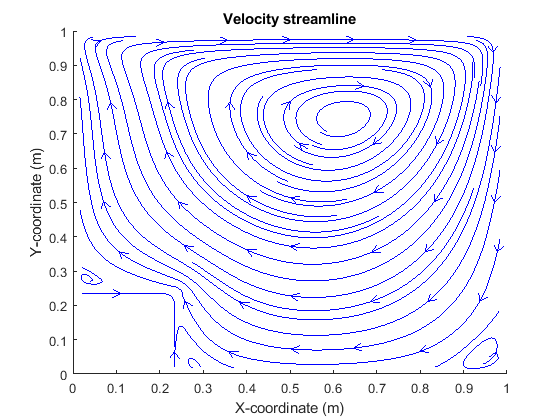

To solve this problem, the boundary conditions must be modified to account for a corner obstacle in the domain. There are many possible solutions to this problem, but perhaps the easiest is to write two new functions for applying velocity and pressure boundary conditions. Open the following code and use the given template for those functions.

% open("project/singlePhaseFlowSolver_project1")

 To successfully introduce a corner obstacle, the same procedure for the wall domain boundary conditions can be applied. These include a no penetration and no slip condition along the wall. No penetration condition is straight forward; as in our case, the wall lines up exactly with the location of the velocity normal to the wall, such that those values can be set to zero. The no slip boundary condition requires us to utilize the ghost cells, such that the average velocity at the wall is equal to zero.


$$u_{ghost} = -u \\
v_{wall} = 0$$


This boundary condition should wrap the intermediate velocity function to ensure it is applied when calculating $u^*$, $v^*$, and when solving the pressure Poisson equation. In addition, velocity within the obstacle should also be set to zero.

 When solving the pressure Poisson equation, the coefficients must also be set accordingly. At the obstacle, there is a zero pressure gradient such that the resulting pressure equation is similar to equation $(\mathcal{m)$ from the previous section. 

### ** Project 2**

Solve for flow over a backward facing step with the following boundary conditions:

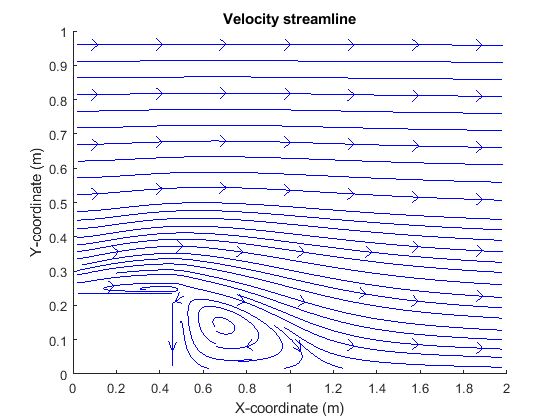

The solution to this problem is similar to how boundary conditions were applied in the previous project. However, in this case, the boundary conditions must be changed over the real domain boundary. On the left wall set the $u$ wall velocity equal to the inlet velocity. On the right wall, use a open boundary condition setting the $u$ wall velocity equal to the face velocity to its left. Both walls contain a no slip $v$ velocity. The top wall is no penetration, but contains a slip $u$ velocity. The bottom wall is no slip no penetration. The pressure coefficients on the inlet wall, must no longer be set to zero, since those coefficients now exist. See the above section on the pressure solver for reference.

% open("project/singlePhaseFlowSolver_project2.m")

### ** Project 3**

Use the built in conjugate gradient pressure solver in MATLAB instead of the SOR solver function. Write a new function called pressureOptimized() that builds a tri-diagonal block matrix using sparse matrices.

% open("project/singlePhaseFlowSolver_project3.m")

### Next section

As you may have noticed, our flow solver only deals with a single phase of fluid. To learn about introducing an interface, and performing interface advection with the volume-of-fluid method open up the following teaching module in this course.

% open("../InterfaceAdvection/interfaceAdvection_teachingModule.mlx")

## **References**

Anderson, J. D. (1995). *Computational Fluid Dynamics: The basics with applications*. McGraw-Hill. 

Patankar, S. (2018). *Numerical heat transfer and fluid flow*. Taylor & Francis.

Successive over-relaxation. (2023, July 21). In *Wikipedia*. https://en.wikipedia.org/wiki/Successive_over-relaxation